taken from "Reflections and Refractions in Ray Tracing" by Bram de Greve Nov, 13, 2006

# Reflections and Refractions in Ray Tracing

## Introduction

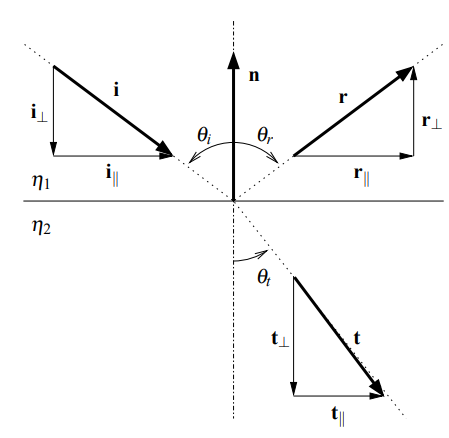

## Using reflection_func

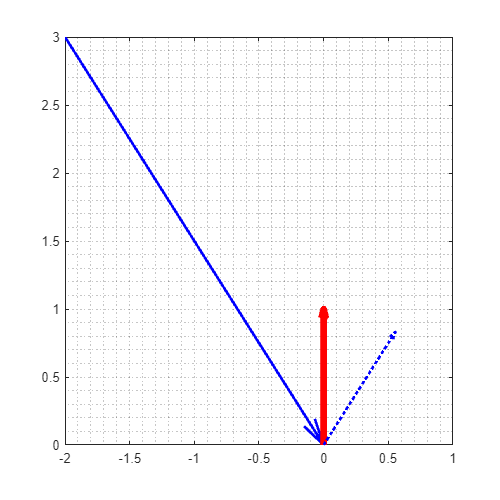

ivec = [2;-3];
nvec = [0;1];

rvec = reflection_func(ivec, nvec);
figure('Position',[0 0 500 500])
quiver(-ivec(1),-ivec(2),ivec(1),ivec(2), 'LineWidth',2, AutoScale='on', AutoScaleFactor=1.0, LineStyle='-', Color='b'), hold on
quiver(0,0,0,1, 'LineWidth',5, AutoScale='on', AutoScaleFactor=1.0, LineStyle='-', Color='r')
quiver(0,0,rvec(1),rvec(2), 'LineWidth',2, AutoScale='on', AutoScaleFactor=1.0, LineStyle=':', Color='b')
grid minor

## Using refraction_func

ivec = [2;-3];
nvec = [0;1];
eta_i = 1;
eta_t = 1.5;

tvec = refraction_func(ivec, nvec, eta_i, eta_t);

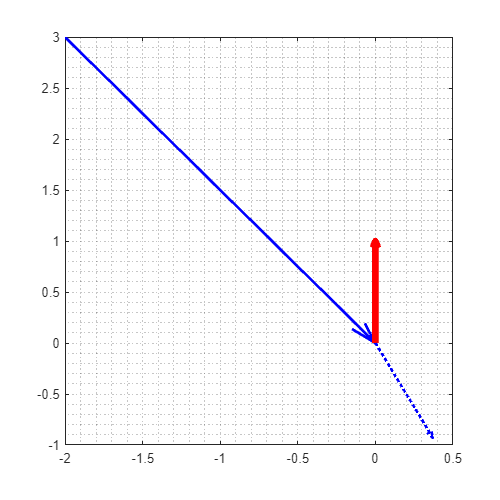

figure('Position',[0 0 500 500])
% ivec = ivec/norm(ivec);
quiver(-ivec(1),-ivec(2),ivec(1),ivec(2), 'LineWidth',2, AutoScale='on', AutoScaleFactor=1.0, LineStyle='-', Color='b'), hold on
quiver(0,0,0,1, 'LineWidth',5, AutoScale='on', AutoScaleFactor=1.0, LineStyle='-', Color='r')
quiver(0,0,tvec(1),tvec(2), 'LineWidth',2, AutoScale='on', AutoScaleFactor=1.0, LineStyle=':', Color='b')
grid minor

## Using intersect_func

ivec = [2;-3];
nvec = [0;1];
eta_i = 1;
eta_t = 1.5;

Q = [-2;2];
P = [0;0];

R = intersect_func(ivec, nvec, P, Q)

R =    -0.6667
    0.0000


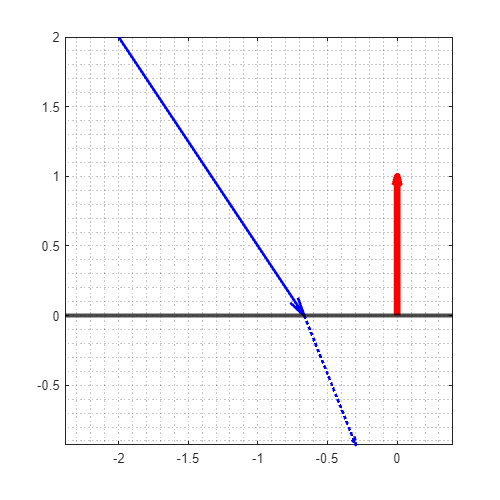

figure('Position',[0 0 500 500])
quiver(Q(1), Q(2),R(1)-Q(1),R(2)-Q(2), 'LineWidth',2, AutoScale='on', AutoScaleFactor=1.0, LineStyle='-', Color='b'), hold on
yline(0, 'LineWidth',3, Color='k')
quiver(0,0,0,1, 'LineWidth',5, AutoScale='on', AutoScaleFactor=1.0, LineStyle='-', Color='r')
quiver(R(1),R(2),tvec(1),tvec(2), 'LineWidth',2, AutoScale='on', AutoScaleFactor=1.0, LineStyle=':', Color='b')
grid minor
axis equal